## Proportional-Derivative (PD) control design to change the step response of a 2nd order system

### Learning Outcomes

The student should be able to 

- Compute the rise time, overshoot, settling time and steady-state value of the step response of a system.

- Compute a PD controller with feedforward gain to change the transient step response of a second-order system, including the damping ratio and damped frequency.

- Design a PD controller with feedforward gain that ensures there is no steady-state error between the output and a constant reference signal for a second-order system. 

The figures below are from KJ Åström and RM Murray. Feedback Systems: An Introduction for Scientists and Engineers. Princeton University Press, 2020.

## 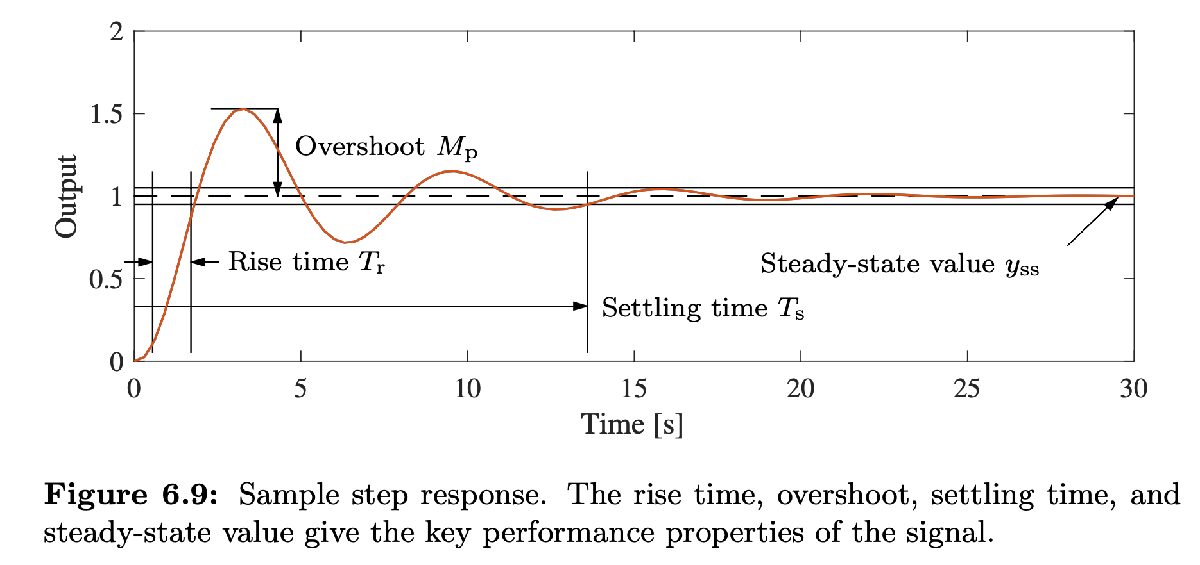

## 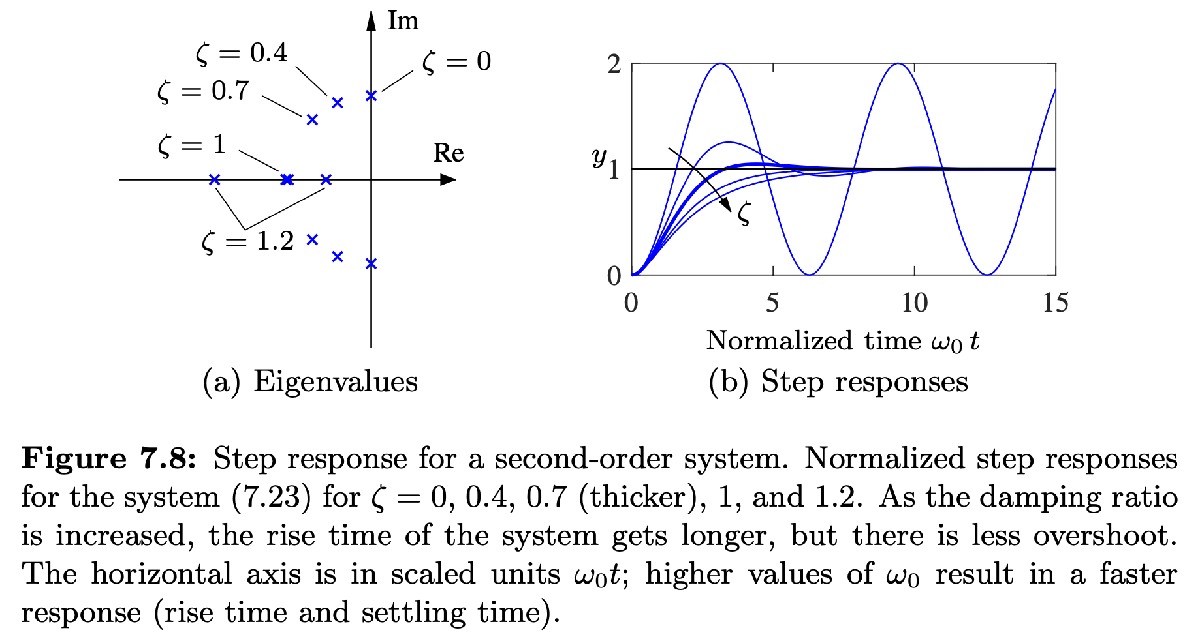

## 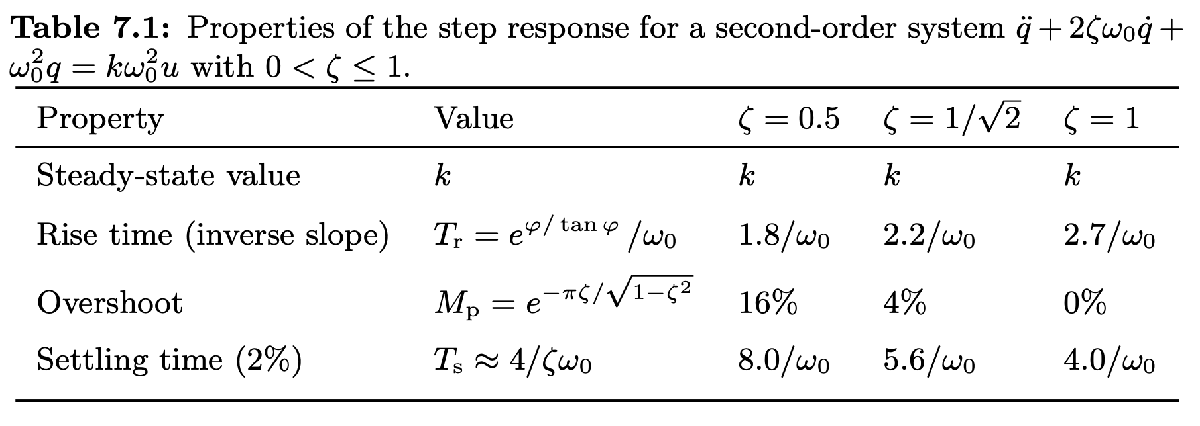

%clear all
syms zeta omega_0 s  t k k_P k_D k_f real
syms zeta_c omega_c k_c real

## Open-loop system


$$\dot{x} = Ax+Bu$$



$$y = Cx$$


System


$$\ddot{q}+2\zeta\omega_0\dot{q}+\omega_0^2=k\omega_0^2u$$



$$y=q$$


Let $x_1 = q$ and $x_2 = \dot{q}$, then 

A(zeta,omega_0) = [0 1; -omega_0^2 -2*zeta*omega_0] 

$$A(zeta, omega\_0) = \left(\begin{array}{cc} 0 & 1\\ -{\omega_{0}}^{2} & -2\,\omega_{0}\,\zeta \end{array}\right)$$

B(k,omega_0) = [0; k*omega_0^2]

$$B(k, omega\_0) = \left(\begin{array}{c} 0\\ k\,{\omega_{0}}^{2} \end{array}\right)$$

C = [1 0]

C =      1     0


Characteristic polynomial is $p(s) = \mathrm{det}(sI-A)$ 

p(s) = (det(s*eye(2)-A)) % characteristic polynomial

$$p(s) = {\omega_{0}}^{2}+2\,\zeta \,\omega_{0}\,s+s^{2}$$

Eigenvalues are roots of characteristic polynomial, i.e.


$$\sigma(A) = \{\lambda: p(\lambda) = 0\}$$


%eigs = eig(A) % eigenvalues
eigs = simplify(eig(A))

$$eigs(zeta, omega\_0) = \left(\begin{array}{c} -\omega_{0}\,\left(\zeta -\sqrt{\zeta^{2}-1}\right)\\ -\omega_{0}\,\left(\zeta +\sqrt{\zeta^{2}-1}\right) \end{array}\right)$$

## Closed-loop system with PD controller

PD control law with feedforward gain


$$u = -k_P q - k_D \dot{q} +k_f r = -k_P y - k_D \dot{y} +k_f r=-k_P x_1 - k_D x_2 +k_f r  = -[k_P\ k_D]x+k_fr= -Kx+k_f r$$


Closed-loop system becomes


$$\dot{x} = A_cx+B_cr=(A-BK)x+Bk_fr$$


We want to design a closed-loop system with damping factor $\zeta_c$, natural frequency $\omega_c$ and steady-state value $k_c$.

K = [k_P k_D]

$$K = \left(\begin{array}{cc} k_{P} & k_{D} \end{array}\right)$$

A_c = A-B(k,omega_0)*K % closed-loop dynamics matrix

$$A\_c(zeta, omega\_0) = \left(\begin{array}{cc} 0 & 1\\ -{\omega_{0}}^{2}-k\,k_{P}\,{\omega_{0}}^{2} & -k\,k_{D}\,{\omega_{0}}^{2}-2\,\zeta \,\omega_{0} \end{array}\right)$$

B_c = B(k,omega_0)*k_f % closed-loop input matrix

$$B\_c = \left(\begin{array}{c} 0\\ k\,k_{f}\,{\omega_{0}}^{2} \end{array}\right)$$

p_c = collect(det(s*eye(2)-A_c),s) % closed-loop characteristic polynomial

$$p\_c(zeta, omega\_0) = s^{2}+\left(k\,k_{D}\,{\omega_{0}}^{2}+2\,\zeta \,\omega_{0}\right)\,s+{\omega_{0}}^{2}+k\,k_{P}\,{\omega_{0}}^{2}$$

p_c = charpoly(A_c) % closed-loop characteristic polynomial

$$p\_c(zeta, omega\_0) = \left(\begin{array}{ccc} 1 & k\,k_{D}\,{\omega_{0}}^{2}+2\,\zeta \,\omega_{0} & {\omega_{0}}^{2}+k\,k_{P}\,{\omega_{0}}^{2} \end{array}\right)$$

p_d = charpoly(A(zeta_c,omega_c)) % desired closed-loop characteristic polynomial

$$p\_d = \left(\begin{array}{ccc} 1 & 2\,\omega_{c}\,\zeta_{c} & {\omega_{c}}^{2} \end{array}\right)$$

## Solve for controller gains

Ks = solve(p_c == p_d, [k_P k_D]); % equate coefficients of characteristic polynomial
k_Ps = Ks.k_P % proportional gain

$$k\_Ps = -\frac{{\omega_{0}}^{2}-{\omega_{c}}^{2}}{k\,{\omega_{0}}^{2}}$$

k_Ds = Ks.k_D % derivative gain

$$k\_Ds = \frac{2\,\left(\omega_{c}\,\zeta_{c}-\omega_{0}\,\zeta \right)}{k\,{\omega_{0}}^{2}}$$

k_fs = solve(B(k_c,omega_c) == B_c, k_f) % feedforward gain

$$k\_fs = \frac{k_{c}\,{\omega_{c}}^{2}}{k\,{\omega_{0}}^{2}}$$

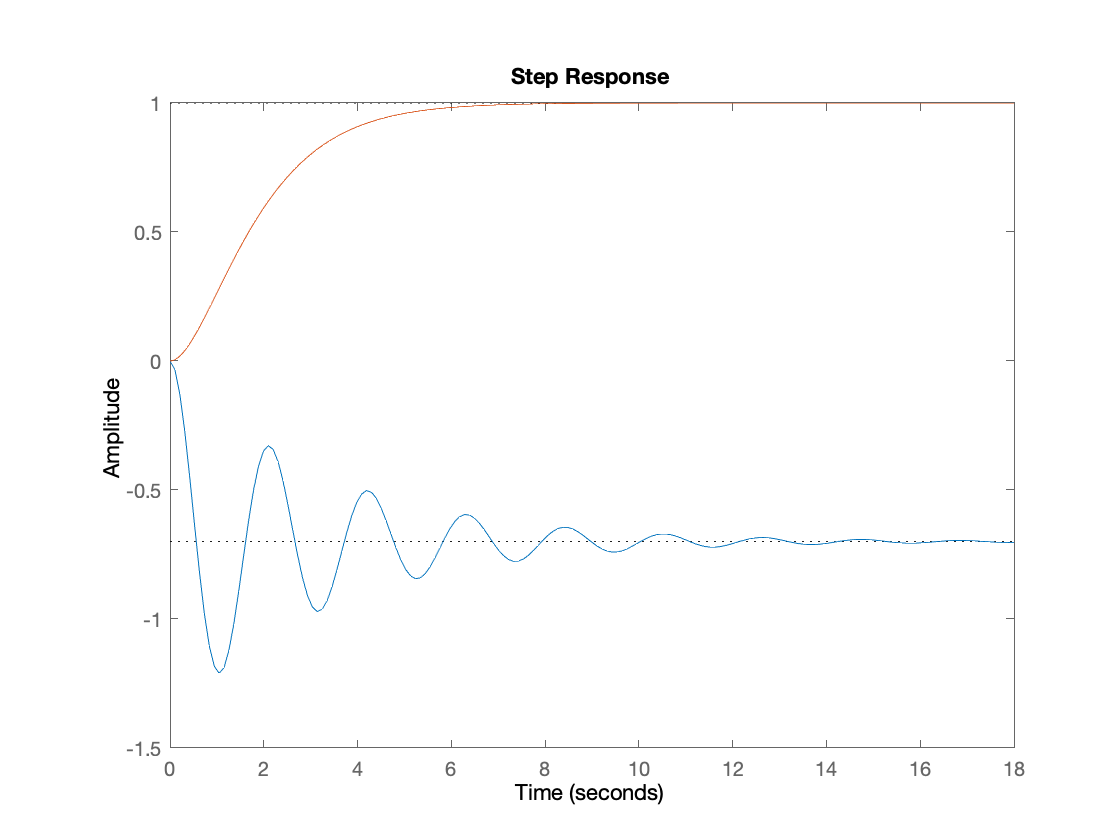

k =-0.7;
k_c = 1;
zeta = 0.1;
zeta_c = 1;
omega_0 = 3;
omega_c = 1;
k_P = eval(k_Ps);
k_D = eval(k_Ds);
k_f = eval(k_fs);
olsys = ss(eval(A), eval(B), C, 0);
clsys = ss(eval(A_c), eval(B_c), C, 0);
step(olsys,clsys)

stepol = stepinfo(olsys)

stepol = struct with fields:
        RiseTime: 0.3757
    SettlingTime: 12.7910
     SettlingMin: -1.2104
     SettlingMax: -0.3279
       Overshoot: 72.9156
      Undershoot: 0
            Peak: 1.2104
        PeakTime: 1.0472


stepcl = stepinfo(clsys)

stepcl = struct with fields:
        RiseTime: 3.3583
    SettlingTime: 5.8341
     SettlingMin: 0.9019
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 11.9274
